# Final Project Notebook

# Diffusion of Air Bubbles in Ice

## By: Lorenzo Caseiro and Matthew Adams

## EAS 4610

## Fall 2023

## **Introduction**

    Glacial ice on the Earth can provide evidence of the state of the planet's past climatic conditions. Air can be trapped within the ice and act as a time capsule that records the atmospheric composition of times past. The air is trapped when continual snowfall buries it under deeper layers of snow until the layer eventually solidifies to ice under increased pressure. This is known as the "bubble closeoff depth" and it is the point at which the bubbles are fully formed and solidified within the ice (Bender et al 1997). The air bubbles provide evidence of certain trace gases, such as methane or carbon dioxide, and their concentration at the time the ice formed (Legend and Mayewski 1997).

    Many modern day researchers use these gas bubbles to measure past climate conditions, and it is invaluable in determining the anthropogenic changes to the Earth's climate. Much of the contmeporary study of this topic focuses on extracting ice cores from the glacial ice sheets that hold the trapped bubbles of air. The ice cores, and the gas bubbles within them, can be studied for paleoclimatologic and paleoceanographic purposes. However, this model, created using information from "Mathematical Modeling of earth's Dynamical Systems: A Primer", does not focus specifically on the results that ice cores can yield. Instead, it models an important consideration that is essential for obtiaing accurate results from the study of ice cores: diffusion of gas bubbles within glacial ice. Gas trapped in glacial ice can diffuse according to Fick's law, and this model seeks to follow how gas would diffuse within a given ice sheet (Singerland and Kump 2006). This information allows for proper tracking of gas within the ice and will yield more accurate results when reconstructing paleoclimate concentrations.

## **Equations**

    The most important process this model uses is the advection-diffusion equation. This equation can be used to describe phenomena that undergo both advection and diffusion within the system. Diffusion is defined as the movement of molecules across a concentration gradient, and it is an essential process when studying air bubbles trapped in ice (Slingerland and Kupp 2006). Using this law, the model can simulate changes in concentration of a desired gaseous species in terms of both time and space (or depth in this case). The Oxford English Dictionary defines advection as "the transfer of heat or matter by the flow of a fluid." Advection is another important process to consider for this model as new layers of snowfall continue to pile on ice sheets and cause advective transport within the system. The advection-diffusion utilizes partial derivatives to model both of the previously described physical processes in a system.

## 
$$\frac{\partial J}{\partial t}+u*\frac{\partial J}{\partial x}=D*\frac{\partial^2 J}{\partial x^2 }$$


D = diffusivity

t = time

x = position

J = concentration

u = fluid velocity

**Equation 1: **Advection-diffusion equation

    The above equation utilizes several important parameters that should be defined to further understand the model. Diffusivity, also known as a diffusion coefficient, is a constant that is unique for a given substance that is undergoing diffusion. The diffusion coeffecient in this model utilizes units of square meters per year. The variable used for time, tracked in years, is essential for tracking the changes in concentration of a substance as a function of time. In this model, the position variable refers to the depth of a gas bubble within an ice sheet measured in meters. The fluid velocity variable is derived from the advection portion of the equation and it is defined as the snowfall rate in meters per year in this scenario. Finally, the concentration is the output of the model and describes the concentration of a diffused substance in moles. Additionally, the model uses a diffusion number that is integral for solving the diffusion equation. Similarly to the diffusion number, the advection part of the reaction has a dimensionless parameter, known as the courant number, that must be used to solve the equation. These terms are defined below.

## 
$$C_D =\frac{D*\Delta t}{\Delta x^2 }$$


**Equation 2: **Equation defining the diffusion number term.

## 
$$C=\frac{u*\Delta t}{\Delta x}$$


**Equation 3: **Equation defining the courant number term.

    The discretization of the advection-diffusion equation below is used by this model to solve for unknown concentration values. It isolates an unknown concentration value on one side of the equation, and it can then be used as a marching equation to obtain approximations for concentration.

## (a) $\frac{\partial J}{\mathrm{dt}}+u*\frac{\partial J}{\partial x}-D*\frac{\partial^2 J}{\partial x^2 }=0$

## (b) $\frac{\partial J}{\partial t}=\frac{J_i^{k+1} -J_i^k }{\Delta t}$, $\frac{\partial J}{\partial x}=\frac{J_i^k -J_{i-1}^k }{\Delta x}$, $\frac{\partial^2 J}{\partial x^2 }=\frac{J_{i+1}^k -{2J}_i^k +J_{i-1}^k }{\Delta x^2 }$

## (c) $\frac{J_i^{k+1} -J_i^k }{\Delta t}+u*\frac{J_i^k -J_{i-1}^k }{\Delta x}-D*\frac{J_{i+1}^k -{2J}_i^k +J_{i-1}^k }{\Delta x^2 }=0$

## (d) $J_i^{k+1} =J_i^k +\Delta t\left(-u*\frac{J_i^k -J_{i-1}^k }{\Delta x}+D*\frac{J_{i+1}^k -{2J}_i^k +J_{i-1}^k }{\Delta x^2 }\right)$

**Equation 4: **Discretization of advection-diffusion equation. (Note: k terms refer to time while i terms refer to space).

***boundary conditions

    Many of the intial conditions of the model changed based on the simulation being done, and these changes will be discussed in more detail below for each individual case. However, the original model proposed by Slingerland and Kump had a set of intial conditions that this model also utilized in some simulations. The model from "Mathematical Modeling of Earth's Dynamical Systems: A Primer" defined the snowfall rate to be a constant 0.1 meters per year and the time as a period from present day to 500 years into the future. Also, it is important to note that the diffusion coeffecient was initialized to 3.15e-4 meters squared per year.

    It is important to note that this model assumes the compaction of snow to be negligible. Also, carbon dioxide concentrations in the atmosphere were assumed for historical and future periods to simplify the model. The starting carbon dioxide value was assumed to be 280 ppm in 1900, and it is assumed to reach 450 ppm by the year 2100 for the sake of this model.

## **Numerical Method**

## **Code and Results**

### **Initialize parameters and grid**

% Define Parameters
CO2_solub = 2*10^(-6); %mol/(cm^3*ppm)
CO2_solub = CO2_solub/(1*10^(-6)); %mol/(m^3*ppm)
D = 1*10^(-7); %cm^2/s
D = D*3153.6; %m^2/yr
w = 0.1; %m/yr
t_final = 500; %yr

% Define Grid
delta_t = 0.005; %yr
t = 0:delta_t:t_final; %yr
n_t = length(t);

x_final = t_final*w; %m
delta_x = 1; %m
x = 0:delta_x:x_final+delta_x; %m
n_x = length(x);

C_num = w*delta_t/delta_x; %Courant Number
D_P = D*delta_t/(delta_x^2);

### **Solve for carbon dioxide concentration over time**

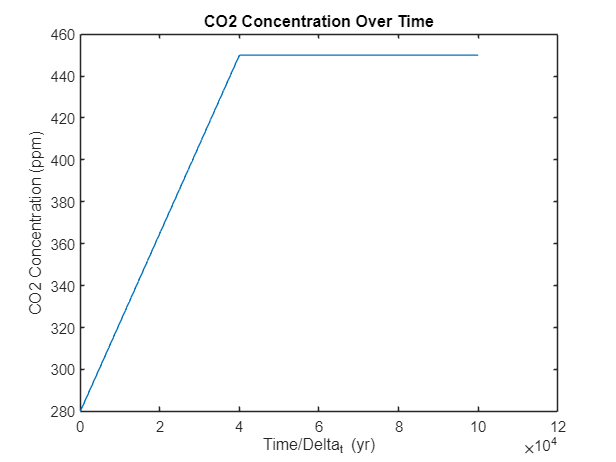

% Solve
C_pre1900 = 280; %ppm
C_post2100 = 450; %ppm
C_1900_2100 = linspace(C_pre1900, C_post2100, 200/delta_t); %ppm
for k = 1:(n_t-(200/delta_t))
    C_1900_2100(end+1) = C_post2100;
end

plot(C_1900_2100)
title('CO2 Concentration Over Time');
xlabel('Time/Delta_t (yr)'); ylabel('CO2 Concentration (ppm)')

### **Final year profile with conditions given in text**

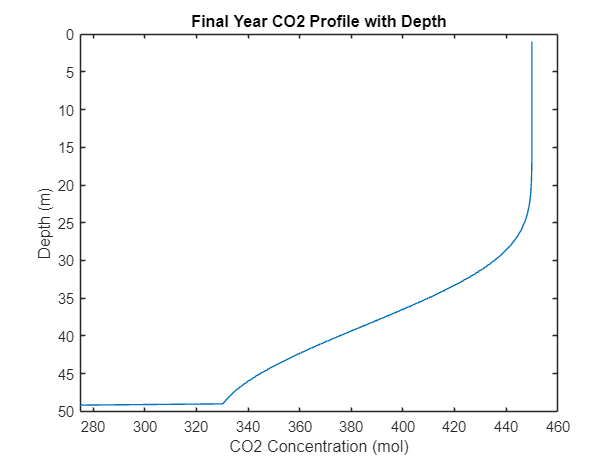

C = zeros(n_x+1,n_t);
C(1,:) = C_1900_2100;

% Prevent Snow from Diffusing into Grid Spaces too Soon
snow = zeros(n_x, n_t);
for k = 1:n_t
    for i = 1:n_x
        if (i - k*delta_t*w) == 0
            snow(i,k) = 2;
        end
        if (i - k*delta_t*w) < 0
            snow(i,k) = 1;
        end
    end
end

for k = 1:(n_t-1)
    for i = 2:(n_x-1)
        if snow(i,k) == 1 %Normal Advection Diffusion
            C(i,k+1) = C(i,k) - C_num*(C(i,k) - C(i-1,k)) + D_P*(C(i+1,k) - 2*C(i,k) + C(i-1,k));
        end
        if snow(i,k) == 2 %No flux boundary
            C(i,k+1) = C(i-1,k);
        end
        if snow(i,k) == 0 %Out of Snow Bounds
            C(i,k+1) = 0;
        end
    end
end


plot(C(:,end-1));
set(gca, 'XDir','reverse');
view([90 -90]);
xlim([0 x_final]);
ylim([275 max(C(:,end))+10]);
xlabel('Depth (m)'); ylabel('CO2 Concentration (mol)');
title('Final Year CO2 Profile with Depth')

### Animation (Run at Own Risk)

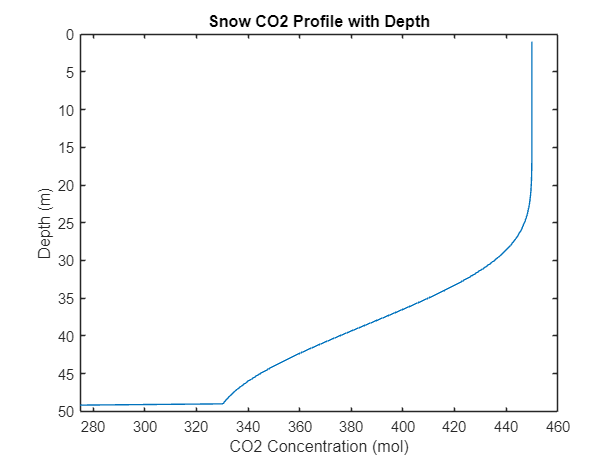

figure;
for i = 1:(n_t/100)
    plot(C(:,i*100))
    set(gca, 'XDir','reverse');
    view([90 -90]);
    xlabel('Depth (m)'); ylabel('CO2 Concentration (mol)');
    title('Snow CO2 Profile with Depth')
    xlim([0 x_final]);
    ylim([275 max(C(:,end))+10]);
    drawnow
end

### **Time 1**

### **Time 2**

### **w 1**

### **w 2**

### **w 3**

### Solve With Matrix (WIP)

% Solve
C_pre1900 = 280; %ppm
C_post2100 = 450; %ppm
C_1900_2100 = linspace(C_pre1900, C_post2100, 200); %ppm
for k = 1:(n_t-200)
    C_1900_2100(end+1) = C_post2100;
end

C = zeros(n_x,n_t);

data_M = [(D_P + C_num)*ones(n_x,1), (1 - D_P - 2*C_num)*ones(n_x,1), C_num*ones(n_x,1)];
M = spdiags(data_M, -1:1, n_x, n_x);

for i = 2:(n_t - 1)
    C(:,i+1) = M\C(:,i);
end

% Plot
figure;
plot(x, C(:, end));
set(gca, 'XDir', 'reverse');
xlabel('Depth (m)');
ylabel('CO2 Concentration (mol)');
title('Final Year CO2 Profile with Depth');

## **Video Walkthrough**

## **References**

Bender, Michael, et al. “Gases in ice cores.” *Proceedings of the National Academy of Sciences*, vol. 94, no. 16, 1997, pp. 8343–8349, https://doi.org/10.1073/pnas.94.16.8343. 

Legrand, Michel, and Paul Mayewski. “Glaciochemistry of polar ice cores: A Review.” *Reviews of Geophysics*, vol. 35, no. 3, 1997, pp. 219–243, https://doi.org/10.1029/96rg03527. 

*Oxford English Dictionary*, www.oed.com/. Accessed 2 Dec. 2023. 

Slingerland, Rudy, and Lee R. Kump. “Advection and Diffusion (Transport) Problems.” *Mathematical Modeling of Earth’s Dynamical Systems: A Primer*, Princeton University Press, Princeton, 2006, pp. 124–125. 